# Relatório de Atividade 11 - Identificação por Subespaço

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Estimação e Identificação de Sistemas 21.2*

*09 de Novembro de 2021*

Esse documento tem por objetivo descrever o método de identificação de um sistema desconhecido por meio de subespaço. Em seguida, serão discutidos quatros exemplos de ordens e sinais de excitação diferente aplicando o método em estudo.

## Introdução

Em contraste com as atividades anteriores, esse documento analisa a estimação de um sistema desconhecido a partir da identificação de um subespaço. Nesse método, o único parâmetro fornecido pelo usuário é a ordem do sistema. Em relação aos métodos parametrizáveis tradicionais, a técnica de identificação por subespaço possuí os seguintes benefícios:

- Não é extremamente sensível a perturbações pequenas nos sinais de entrada, uma vez que não trata com matrizes mal condicionadas (como $P(t)$ no algoritmo de mínimos quadrados);

- Não limita as dinâmicas representativas do modelo, uma vez que não requer parametrização especial para dinâmicas não controláveis, mas observáveis.

O objetivo final desse método é estimar os melhores parâmetros do sistema $A$, $B$, $C$ e $D$ para que o modelo estimado forneça saídas semelhantes à planta real. Para tal, considera-se conhecidas as entradas $u(n)$ e saídas $y(n)$ da planta estimada. A dinâmica do sistema, por sua vez, é dada por:


$$x(n+1) = Ax(n)+Bu(n)$$



$$y(n)=Cx(n)+Du(n)$$


### Unicidade da solução

A solução encontrada para as matrizes $A$, $B$, $C$ e $D$ não é única. Para demonstrar esse problema, considere a multiplicação de ambos os lados da equação de $x(n+1)$ por uma matriz inversível $T$:


$$ \left[\matrix{ T&0 \cr 0&I } \right] 
 \left[\matrix{ x(2)&x(3)&...&x(p+1) \cr y(1)&y(2)&...&y(p)  } \right] =
 \left[\matrix{ T&0 \cr 0&I } \right]  \left[\matrix{ A&B \cr C&D } \right] 
 \left[\matrix{ x(1)&x(2)&...&x(p) \cr u(1)&u(2)&...&u(p)  } \right] $$


para $I$ a matriz identidade. Pode-se reescrever a expressão acima como:


$$ \left[\matrix{ Tx(2)&Tx(3)&...&Tx(p+1) \cr y(1)&y(2)&...&y(p)  } \right] =
\left[\matrix{ TAT^{-1}&TB \cr CT^{-1}&D } \right] 
 \left[\matrix{ Tx(1)&Tx(2)&...&Tx(p) \cr u(1)&u(2)&...&u(p)  } \right] $$


Ou seja, para um mesmo conjunto de entradas e saídas $u(t)$ e $y(t)$, é possível encontrar múltiplos estados $Tx(n)$ que representam a dinâmica planta desconhecida.

### Matrizes de Hankel

Para desenvolver a matemática envolvida no processo de estimação, é importante conhecer as matrizes de bloco de Hankel, as quais representam os sinais $u(n)$ e $y(n)$ como um histórico de linhas:


$$Y_{1|i} =  \left[\matrix{ y(1)&y(2)&...&y(j) \cr y(2)&y(3)&...&y(j+1) \cr \vdots&\vdots&\ddots&\vdots \cr y(i)&y(i+1)&...&y(i+j+1)}\right]$$



$$U_{1|i} =  \left[\matrix{ u(1)&u(2)&...&u(j) \cr u(2)&y(3)&...&u(j+1) \cr \vdots&\vdots&\ddots&\vdots \cr u(i)&u(i+1)&...&u(i+j+1)}\right]$$


Dessa forma, é possível reescrever a dinâmica do sistema como:

$Y_{1|i}=\Gamma_iX_i+H_iU_{1|i}$ **(Eq. 1)**

$X_{i+1}=A^iX_1+\Delta_iU_{1|i}$ **(Eq.2)**

para $X_i =  \left[\matrix{ x(i)&x(i_1)&...&x(i+j-1) } \right]$, $\Gamma_i= \left[\matrix{ C&CA&...&CA^{i-1} } \right]^T$, $\Delta_i= \left[\matrix{ A^{i-1}B&A^{i-2}B&...&B } \right]$ e $H_i =  \left[\matrix{ D&0&0&...&0 \cr CB&D&0&...&0 \cr CAB&CB&D&&0 \cr \vdots&\vdots&&\ddots&\vdots\cr CA^{i-2}B&CA^{i-3}B&...&CB&D}\right]$.

### Equacionamento de estimação

Inicialmente, isola-se $X_i$ na equação (1):


$$X_i = \Gamma_i^*Y_{1|i}-\Gamma_i^*H_iU_{1|i}$$


para $\Gamma_i^*$ a pseudo-inversa de $\Gamma_i$. Substituindo na equação (2):


$$X_{i+1} = A^i\Gamma_i^*Y_{1|i}- A^i\Gamma_i^*H_iU_{1|i}+\Delta_iU_{1|i} = L_iW_{1|i}$$
 

para $L_i= \left[\matrix{ \Delta_i-A^i\Gamma_i^*H_i&A^i\Gamma_i^* } \right]$ e $W_{1|i} = \left[\matrix{ U_{1|i}& Y_{1|i} } \right]^T$. Logo, é possível computar a relação entrada-saída no instante $i+1$ como:


$$Y_{i+1|2i} = \Gamma_iX_{i+1}+H_iU_{i+1|2i} = \Gamma_iL_iW_{1|i}+H_iU_{i+1|2i}$$


A partir da relação matricial acima, é evidente que $Y$ pertence ao subespaço definido pelas linhas de $U$ e do vetor linha $X$. Para desconsiderar a contribuição das entradas $U$ na saída $Y$, é necessário projetar $Y$ em um espaço perpendicular ao subespaço definido por $U$. Dessa forma:


$$Y_{i+1|2i}/U_{i+1|2i}^\perp = \Gamma_iL_iW_{1|i}/U_{i+1|2i}^\perp+H_iU_{i+1|2i}/U_{i+1|2i}^\perp $$


para $U_{i+1|2i}^\perp$ o espaço perpendicular ao plano definido pelos vetores linhas de $U_{i+1|2i}$ e $A/B^\perp = A\big(I-B^T(BB^T)^*B\big)$. Detalhes sobre a definição da operação de projeção podem ser encontrada na literatura referenciada [1]. Como $B/B^\perp=0$, é possível reescrever a relação acima como:


$$Y_{i+1|2i}/U_{i+1|2i}^\perp = \Gamma_iL_iW_{1|i}/U_{i+1|2i}^\perp$$


Isolando $\Gamma_iL_i$, encontra-se:


$$\Gamma_iL_i = [Y_{i+1|2i}/U_{i+1|2i}^\perp][W_{1|i}/U_{i+1|2i}^\perp]^*$$


Multiplicando ambos os lados por $W_{1|i}$ e considerando que $X_{i+1} = L_iW_{1|i}$, tem-se:


$$\Gamma_iX_{i+1} = [Y_{i+1|2i}/U_{i+1|2i}^\perp][W_{1|i}/U_{i+1|2i}^\perp]^*W_{1|i}$$


Os termos na direita do equacionamento acima são conhecidos, enquanto os termos à esquerda devem ser estimados. Considerando $O_{i+1}= [Y_{i+1|2i}/U_{i+1|2i}^\perp][W_{1|i}/U_{i+1|2i}^\perp]^*W_{1|i}$, tem-se:


$$O_{i+1} = \left[\matrix{ C&CA&...&CA^{i-1} } \right]^T\left[\matrix{ x(i)&x(i_1)&...&x(i+j-1) } \right]$$


Observando a relação acima, é claro que cada linha de $O$ é um subespaço dos vetores linhas de $X$. Em adição, a matriz $O$ é composta por vetores linha linearmente dependentes. Logo, o posto de $O$ é equivalente ao posto de $X$, o qual representa a ordem do sistema simulado $j$. 

Os valores exatos de $\Gamma_i$ e $X_{i+1}$ são obtidos a partir da decomposição de valores singulares de $O_{i+1}$:


$$O_{i+1} = \Gamma_iX_{i+1} = PSV = PS^{1/2}TT^{-1}S^{1/2}V$$


para $P$ e $V$, respectivamente, matrizes de mesma dimensão que $C$ e $X$. Logo, tem-se que $X_{i+1} = T^{-1}S^{1/2}V$ e $\Gamma_i=PS^{1/2}T$. Como a estimativa do vetor de estados $\hat{X}_{i+1}$ é proporcional em relação ao vetor real $X_{i+1}$ por uma constante $T$, é claro que $\hat{X}_{i+1}= TX_{i+1} = S^{1/2}V$.

A matriz $V|$ representa $V$ sem a última coluna. Analogamente, $|V$ representa a matriz $V$ sem a primeira coluna. Analiticamente, encontra-se que:


$$\hat{X}_{i+2}|=S^{1/2}|V$$



$$\hat{X}_{i+1}|=S^{1/2}V|$$


Logo, o espaço de estados da dinâmica do sistema estimado é dado por:


$$\left[\matrix{\hat{X}_{i+2}|\cr Y_{i+1|2i} } \right]= \left[\matrix{\hat{A}&\hat{B} \cr \hat{C}&\hat{D}} \right]\left[\matrix{\hat{X}_{i+1}|\cr U_{i+1|2i} } \right]$$


Uma vez que se conhece $U_{i+1|2i}$, $Y_{i+1|2i}$, $\hat{X}_{i+2}|$ e $\hat{X}_{i+1}|$, é possível computar as estimativas $\hat{A}$, $\hat{B}$, $\hat{C}$ e $\hat{D}$ como:


$$\left[\matrix{\hat{A}&\hat{B} \cr \hat{C}&\hat{D}} \right]= \left[\matrix{\hat{X}_{i+2}|\cr Y_{i+1|2i} } \right]\left[\matrix{\hat{X}_{i+1}|\cr U_{i+1|2i} } \right]^*=\left[\matrix{ TAT^{-1}&TB \cr CT^{-1}&D } \right] $$


Sendo assim, é evidente que as estimativas dos parâmetros do modelo não devem ser iguais aos valores verdadeiros, uma vez que a constante $T$ é desconhecida. O que o método de identificação por subsespaços propõe é a recuperação de um sistema equivalente ao identificado, isto é, que produzirá a mesma saída quando exposto a uma mesma entrada.

## Desenvolvimento

Para aplicar o método de identificação por subespaços, foram estimados quatro sistemas: um par de primeira ordem, um sistema de segunda ordem, e outro de terceira ordem. Analogamente, cada sistema foi excitado por um sinal $u(t)$ equivalente a uma onda quadrática ou um ruído gaussiano de média nula e variância untária. As especificações de cada exemplo foram dadas pela literatura referenciada [1]. Para a conclusão, serão analisados os polinômios estimados obtidos em relação ao valores reais simulados.

Caso deseje não visualizar os gráficos de entrada e saída estimadas e reais, defina a variável abaixo como `1`.

verbose = 1;
addpath '.\vanoverschee\SUBFUN';

### Exemplo 1: 1ª ordem e onda quadrática

Para o primeiro exercício, foi simulado o seguinte espaço de estados de primeira ordem:


$$x(k+1) = 0.75x(k)+0.3u(k)$$



$$y(k)=0.5x(k)$$


O sistema foi excitado por uma onda quadrada de magnitude unitária e período de 30 amostras, conforme ilustrado na Figura 1. Aplicando o método de identificação por subespaço descrito na seção de Introdução, foram obtidos os seguintes valores:

A = 0.7500

B = 0.4841

C = 0.3099

D = 2.5963e-16

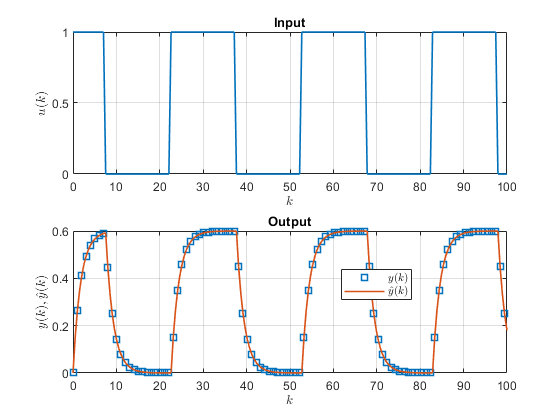

ex01

**Figura 1:** Sinal de excitação do sistema $u(k)$ e de saída estimado $\hat{y}(k)$ e real $y(k)$.

Comparando os valores acima expostos com os valores reais, é evidente que o os parâmetros convergem entre o sistema estimado e o real. Nesse caso, $T\approx1$. 

### Exemplo 2: 3ª ordem e onda quadrática

Já para o segundo exercício, foi simulado o seguinte espaço de estados de terceira ordem:


$$x(k+1) = \left[\matrix{0.9&0&0\cr 0&0.5&0\cr 0&0&0.2} \right]x(k)+\left[\matrix{0.3\cr 0.5\cr 0.8} \right]u(k)$$



$$y(k)=\left[\matrix{1&1&1} \right]x(k)$$


Assim como no Exemplo 1, o sistema foi excitado por uma onda quadrada de magnitude unitária e período de 30 amostras. Aplicando o método de identificação por subespaço descrito na seção de Introdução, foram obtidos os seguintes valores:

A =     0.8604   -0.1404    0.0114
   -0.1401    0.3794    0.1510
    0.0109    0.1537    0.3601


B =     1.0385
    2.0443
   -0.4725


C =     0.7863    0.3776   -0.0242


D = 3.0161e-16

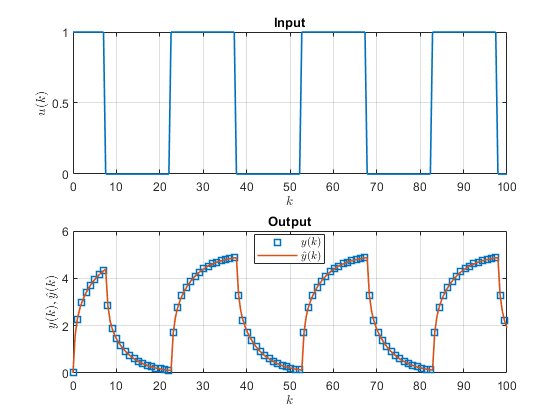

ex02

**Figura 2:** Sinal de excitação do sistema $u(k)$ e de saída estimado $\hat{y}(k)$ e real $y(k)$.

Comparando os valores acima apresentados e os valores reais de $A$, $B$, $C$ e $D$, é evidente que a constante $T$ é não unitária. Entretanto, observando a Figura 2, apesar de $\hat{A}$ não ser uma matriz diagonal, $\hat{B}\neq B$ e $\hat{C}\neq C$, a saída do sistema estimado $\hat{y}(k)$ equivale a saída real simulada $y(k)$. Ou seja, a planta estimada e o modelo estimado são sistemas equivalentes.

### Exemplo 3: 1ª ordem e ruído branco

O terceiro exemplo é semelhante ao primeiro exercício, porém com um sinal de excitação $u(t)$ equivalente ao ruído branco, conforme ilustrado na Figura 3. Foi simulado o seguinte espaço de estados de primeira ordem:


$$x(k+1) = 0.85x(k)+0.3u(k)$$



$$y(k)=-0.5x(k)$$


Aplicando o método de identificação por subespaço descrito na seção de Introdução, foram obtidos os seguintes valores:

A = 0.8500

B = 0.3383

C = -0.4434

D = 3.7496e-17

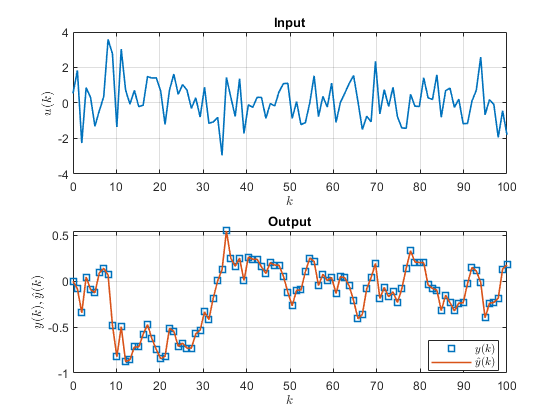

ex03

**Figura 3:** Sinal de excitação do sistema $u(k)$ e de saída estimado $\hat{y}(k)$ e real $y(k)$.

Assim como no Exemplo 1, os parâmetros estimados convergem para os valores reais. Nesse caso, $T\approx1$. 

### Exemplo 4: 2ª ordem e ruído branco

Por fim, para o último exemplo, foi simulado o seguinte espaço de estados de segunda ordem:


$$x(k+1) = \left[\matrix{0.9&0\cr 0&0.5} \right]x(k)+\left[\matrix{0.1\cr 0.3} \right]u(k)$$



$$y(k)=\left[\matrix{1&1} \right]x(k)$$


Assim como no Exemplo 3, o sistema foi excitado por um ruído branco. Aplicando o método de identificação por subespaço descrito na seção de Introdução, foram obtidos os seguintes valores:

A =     0.7595    0.1990
    0.1832    0.6405


B =     0.5277
   -0.2615


C =     0.6397   -0.2388


D = 5.2757e-17

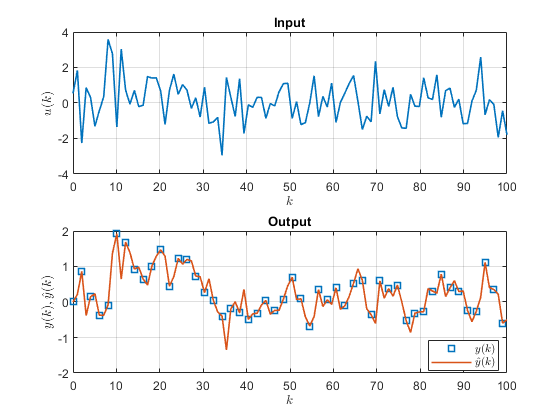

ex04

**Figura 4:** Sinal de excitação do sistema $u(k)$ e de saída estimado $\hat{y}(k)$ e real $y(k)$.

De modo semelhante ao Exemplo 2, é evidente que a constante $T$ é não unitária. Entretanto, observando a Figura 4, a saída do sistema estimado $\hat{y}(k)$ equivale a saída real simulada $y(k)$. Ou seja, a planta estimada e o modelo estimado são sistemas equivalentes.

## **Referências bibliográficas**

[1] VAN OVERSHEE, DE MOOR. **Subspace identification for linear systems**. Kluewer Academic, Boston, ISBN 978-1-4613-0465-4.